# 雷达线性调频(LFM)信号仿真与脉冲压缩

clear; clc; close all;

## 1. 参数设置

c = 3e8;                % 光速 (m/s)
T = 10e-6;              % 脉冲宽度 (10us)
B = 30e6;               % 信号带宽 (30MHz)
K = B / T;              % 调频斜率 (Hz/s)
Fs = 2 * B;             % 采样率 (遵循奈奎斯特采样定理，这里取2倍带宽)
Ts = 1 / Fs;            % 采样时间间隔
N = round(T / Ts);      % 单个脉冲的采样点数

## 2. 生成发射信号 (Transmit Signal)

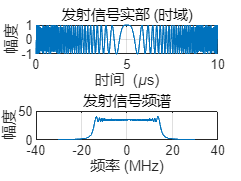

t_pulse = (0:N-1) * Ts;               % 脉冲的时间轴
% 生成复数基带LFM信号: exp(j * pi * K * t^2)
St = exp(1j * pi * K * (t_pulse - T/2).^2);

figure('Name', '发射信号分析');
subplot(2,1,1);
plot(t_pulse*1e6, real(St));
title('发射信号实部 (时域)'); xlabel('时间 (\mus)'); ylabel('幅度'); grid on;

subplot(2,1,2);
f = linspace(-Fs/2, Fs/2, N);
S_freq = fftshift(fft(St));
plot(f/1e6, abs(S_freq));
title('发射信号频谱'); xlabel('频率 (MHz)'); ylabel('幅度'); grid on;

## 3. 模拟接收回波 (Received Signal)

设定目标参数

R_target = 1500;        % 目标距离 1500米
delay = 2 * R_target / c; % 双程延时
delay_points = round(delay / Ts); % 延时对应的采样点数

% 构造包含回波的总接收信号（比单脉冲长，以便观察延时）
total_points = 4000;    % 总仿真时间点数
Sr = zeros(1, total_points);

% 将发射信号放入接收向量中，并加上延时
% 注意：实际接收会有幅度衰减，这里简化假设幅度为 1
if (delay_points + N <= total_points)
    Sr(delay_points + 1 : delay_points + N) = St;
else
    error('目标距离太远，超出仿真范围，请增加 total_points');
end

% 添加高斯白噪声 (AWGN)
SNR_dB = 10;            % 信噪比
Sr = awgn(Sr, SNR_dB, 'measured');

## 4. 脉冲压缩 (Pulse Compression / Matched Filtering)

匹配滤波器系数是发射信号的时间反转并取共轭 h(t) = s*(-t)

Matched_Filter = conj(fliplr(St));

% 进行卷积运算（时域匹配滤波）
So = conv(Sr, Matched_Filter);

% 归一化处理（为了绘图好看）
So = So / max(abs(So));

## 5. 结果转换与绘图

转换时间轴为距离轴 卷积后的序列长度是 length(Sr) + length(Filter) - 1

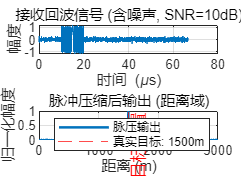

t_out = (0:length(So)-1) * Ts;
% 为了让0时刻对齐脉冲压缩的峰值，需要减去脉冲自身的延时效应（通常滞后一个脉宽）
r_axis = (t_out - T) * c / 2;

figure('Name', '脉冲压缩结果');
subplot(2,1,1);
plot((0:length(Sr)-1)*Ts*1e6, real(Sr));
title(['接收回波信号 (含噪声, SNR=' num2str(SNR_dB) 'dB)']);
xlabel('时间 (\mus)'); ylabel('幅度'); grid on;

subplot(2,1,2);
plot(r_axis, abs(So), 'LineWidth', 1.5);
title('脉冲压缩后输出 (距离域)');
xlabel('距离 (m)'); ylabel('归一化幅度');
grid on;
xlim([0, 3000]); % 限制X轴范围以便看清目标
% 标记实际目标位置
xline(R_target, 'r--', '目标位置');
legend('脉压输出', ['真实目标: ' num2str(R_target) 'm']);

## 6. 理论分辨率计算

Resolution_theory = c / (2 * B);
fprintf('理论距离分辨率: %.2f 米\n', Resolution_theory);

理论距离分辨率: 5.00 米
